# Eclipse 🌑🌒🌓

Analyze the total solar eclipse

2024-04-08

## Context

In this tutorial, we will show how to use MATLAB with the SunPy community Python library for Solar Physics

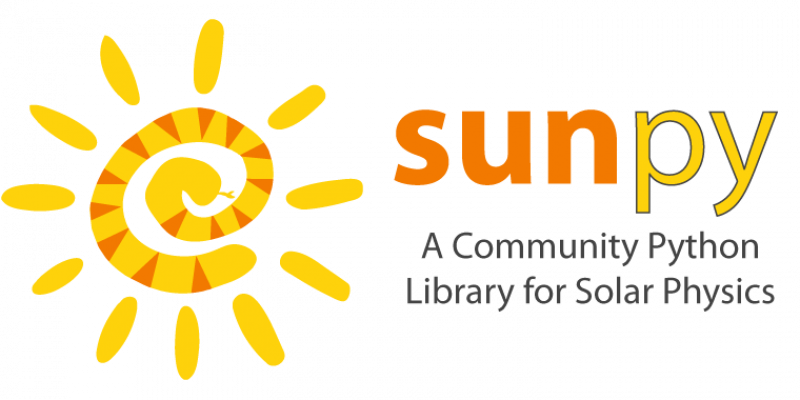

## Resources

- [https://github.com/yanndebray/matlab-with-python-book](https://github.com/yanndebray/matlab-with-python-book)

- [https://docs.sunpy.org/en/stable/generated/gallery/showcase/eclipse_amount.html](https://docs.sunpy.org/en/stable/generated/gallery/showcase/eclipse_amount.html) 

## Set up environment

setup

Defaulting to user installation because normal site-packages is not writeable
Requiremen

pipshow("sunpy")

Name: sunpy
Version: 5.1.2
Summary: SunPy core package: Python for Solar Physics
Home-page: https://sunpy.org
Author: The SunPy Community
Author-email: sunpy@googlegroups.com
License: BSD 2-Clause
Location: /home/matlab/.local/lib/python3.10/site-packages
Requires: astropy, numpy, packaging, parfive, pyerfa
Required-by: 


## Import data with Python live task

% Python code input
pycode4 = [...
"import astropy.units as u",...
"from astropy.coordinates import EarthLocation, solar_system_ephemeris",...
"from astropy.time import Time",...
"from sunpy.coordinates import sun",...
"import numpy as np",...
"import pandas as pd",...
"",...
"# Define the geodetic coordinates",...
"latitude = 29.6 * u.deg",...
"longitude = -98.5 * u.deg  # Note that the longitude should come first",...
"",...
"# Create the EarthLocation object",...
"location = EarthLocation.from_geodetic(longitude, latitude)",...
"max2023 = Time('2023-10-14 16:54')",...
"max2024 = Time('2024-04-08 18:35')",...
"",...
"time = max2024",...
"",...
"# Define an array of observation times centered around the time of interest",...
"times = time + np.concatenate([np.arange(-120, -5) * u.min,",...
"                                np.arange(-300, 300) * u.s,",...
"                                np.arange(5, 121) * u.min])",...
"",...
"# Create an observer coordinate for the time array",...
"observer = location.get_itrs(times)",...
"",...
"# Calculate the eclipse amounts using a JPL ephemeris",...
"with solar_system_ephemeris.set('de440s'):",...
"    amount = sun.eclipse_amount(observer)",...
"    amount_minimum = sun.eclipse_amount(observer, moon_radius='minimum')",...
"",...
"# Calculate the start/end points of partial/total solar eclipse",...
"partial = np.flatnonzero(amount > 0)",...
"if len(partial) > 0:",...
"    print(""Eclipse detected:"")",...
"    start_partial, end_partial = times[partial[[0, -1]]]",...
"    print(f""  Partial solar eclipse starts at {start_partial} UTC"")",...
"",...
"    total = np.flatnonzero(amount_minimum == 1)",...
"    if len(total) > 0:",...
"        start_total, end_total = times[total[[0, -1]]]",...
"        print(f""  Total solar eclipse starts at {start_total} UTC\n""",...
"                f""  Total solar eclipse ends at {end_total} UTC"")",...
"    print(f""  Partial solar eclipse ends at {end_partial} UTC"")",...
"",...
"df = pd.DataFrame({'time': times.to_datetime(), 'amount': amount, 'amount_minimum': amount_minimum})",...
""...
];

[latitude, longitude, df] = pyrun(pycode4, ...
     [ "latitude" "longitude" "df" ])

Eclipse detected:
  Partial solar eclipse starts at 2024-04-08 17:15:00.000 UTC
  Total solar eclipse starts at 2024-04-08 18:33:44.000 UTC
  Total solar eclipse ends at 2024-04-08 18:35:33.000 UTC
  Partial solar eclipse ends at 2024-04-08 19:55:00.000 UTC


latitude =   Python Quantity:

   29.6000

    Use details function to view the properties of the Python object.

    Use double function to convert to a MATLAB array.


longitude =   Python Quantity:

  -98.5000

    Use details function to view the properties of the Python object.

    Use double function to convert to a MATLAB array.


df =   Python DataFrame with properties:

          T: [1x1 py.pandas.core.frame.DataFrame]
         at: [1x1 py.pandas.core.indexing._AtIndexer]
      attrs: [1x1 py.dict]
       axes: [1x2 py.list]
    columns: [1x1 py.pandas.core.indexes.base.Index]
     dtypes: [1x1 py.pandas.core.series.Series]
      empty: 0
      flags: [1x1 py.pandas.core.flags.Flags]
        iat: [1x1 py.pandas.core.indexing._iAtIndexer]
       iloc: [1x1 py.pandas.core.indexing._iLocIndexer]
      index: [1x1 py.pandas.core.indexes.range.RangeIndex]
        loc: [1x1 py.pandas.core.indexing._LocIndexer]
       ndim: [1x1 py.int]
      shape: [1x2 py.tuple]
       size: [1x1 py.int]
     values: [1x1 py.numpy.ndarray]

                       time  amount  amount_minimum
    0   2024-04-08 16:35:00     0.0             0.0
    1   2024-04-08 16:36:00     0.0             0.0
    2   2024-04-08 16:37:00     0.0             0.


% Clean up
clear pycode4;

## Transform Pandas Dataframe to MATLAB Table

% T = table(df)
TT = timetable(df)

TT = 831x2 timetable
            time            amount    amount_minimum
    ____________________    ______    ______________

    08-Apr-2024 16:35:00      0             0       
    08-Apr-2024 16:36:00      0             0       
    08-Apr-2024 16:37:00      0             0       
    08-Apr-2024 16:38:00      0             0       
    08-Apr-2024 16:39:00      0             0       
    08-Apr-2024 16:40:00      0             0       
    08-Apr-2024 16:41:00      0             0       
    08-Apr-2024 16:42:00      0             0       
    08-Apr-2024 16:43:00      0             0       
    08-Apr-2024 16:44:00      0             0       
    08-Apr-2024 16:45:00      0             0       


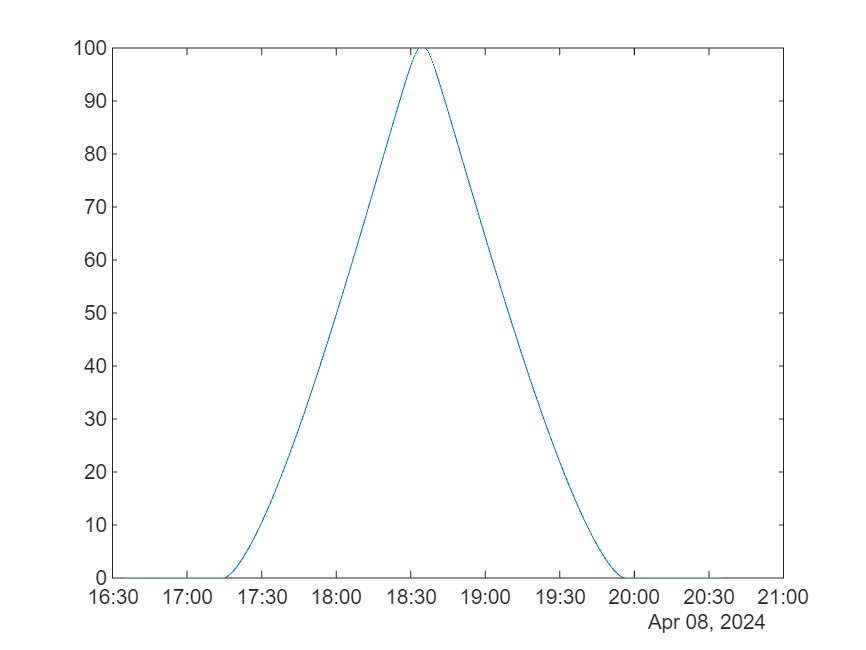

% stackedplot(TT)
plot(TT.time,TT.amount)

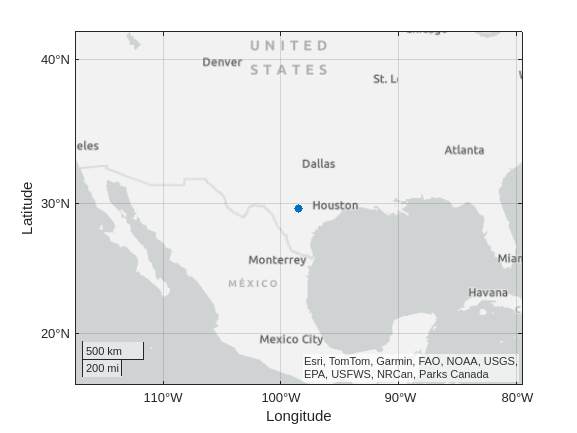

% San Antonio, Texas
lat = py.numpy.array(latitude); lat = double(lat);
lon = py.numpy.array(longitude); lon = double(lon);
geoscatter(lat,lon, 'filled')

## Export to ipynb and md

export('livescript.mlx','README.md');
export('livescript.mlx','notebook.ipynb');